# Auto-generated by the Arduino® Explorer App

Generated on 15-Nov-2025 11:37:41 using MATLAB R2025a Update 1.

## Introduction

This script demonstrates the MATLAB command line workflow of interfacing with an Arduino using functions provided in the MATLAB® Support Package for Arduino® Hardware. You can modify this script to build your own MATLAB function or application.

## Create an Arduino Connection

Create an Arduino connection using the specified device and connection parameters.

clear;
bitebot_path = 'C:\Users\ciepm\OneDrive\Documents\Github\bitebot'

bitebot_path = 'C:\Users\ciepm\OneDrive\Documents\Github\bitebot'

addpath(genpath(bitebot_path))
a = arduino %only valid when arduinosetup is used

a =   arduino with properties:

                  Port: 'COM5'
                 Board: 'Uno'
         AvailablePins: {'D2-D13', 'A0-A5'}
  AvailableDigitalPins: {'D2-D13', 'A0-A5'}
      AvailablePWMPins: {'D3', 'D5-D6', 'D9-D11'}
   AvailableAnalogPins: {'A0-A5'}
    AvailableI2CBusIDs: [0]
             Libraries: {'I2C', 'SPI', 'Servo', 'basicHX711/basic_HX711'}
Show all properties


%a = arduino("COM5", "Uno", Libraries = ["I2C","SPI","Servo"])
methods(a);


Methods for class arduino:

addon              apds9960           canChannel         configurePin       device             motorCarrier       playTone           readDigitalPin     readVoltage        rotaryEncoder      scanI2CBus         servo              shiftRegister      ultrasonic         writeDigitalPin    writePWMDutyCycle  writePWMVoltage    

Methods of arduino inherited from handle.



## Configure Arduino Pins

Configure specified Arduino pins and protocol interfaces.

%set pins
lc_data_pin = "D3";
lc_clock_pin = "D2";
latch_pin = "A0";
pressure_regulator_pin = "D4";
pressure_valve_pin = "D7";
peristaltic_pump_pin = "D8";
vacuum_valve_pin = "D12";

% set outputs
latch = servo(a, latch_pin);
LoadCell = addon(a, 'basicHX711/basic_HX711',{'D3','D2'});
configurePin(a, pressure_regulator_pin, "DigitalOutput");
configurePin(a, pressure_valve_pin, "DigitalOutput");
configurePin(a, peristaltic_pump_pin, "DigitalOutput");
configurePin(a, vacuum_valve_pin, "DigitalOutput");

## Load Cell Setup

input('Clear load cell then press enter to continue...', 's');
cal = calibration(50, 500);
cal.tare_weight = tare(cal, LoadCell);
input('Add 500g mass then press enter to continue...', 's');
cal.scale_factor = scale(cal,LoadCell);
cal_weight = get_weight(cal,LoadCell);
%disp(["Mass of ", cal_weight, "g detected."]);
input('Remove 500g mass then press enter to continue...', 's');

## Read and Write data

Read data from and write data to Arduino pins and protocol interfaces configured above.

% latch_pos = readPosition(latch);
% writePosition(latch, 0.0);
% pause(5); % Wait for X seconds before moving to the next position
% writePosition(latch, 0.5);

## Plot Load Cell

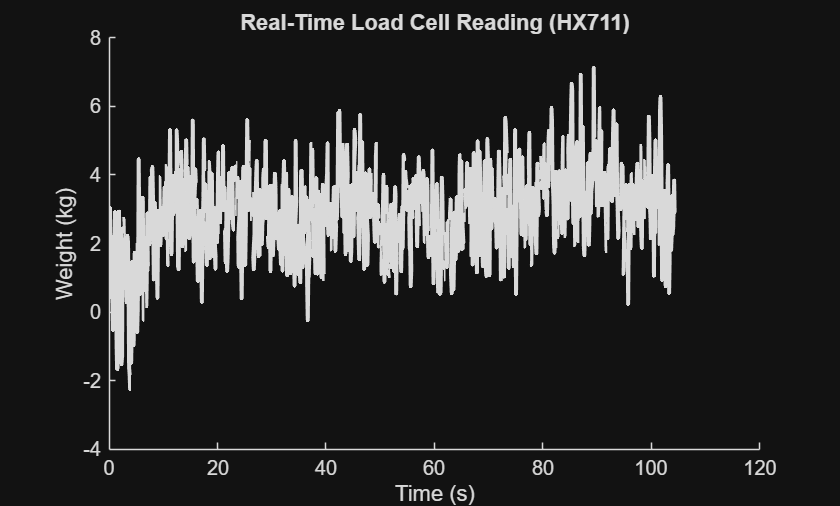

% ---- 2. Setup Plot ----
mass_plot = figure('WindowStyle', 'normal');
h = animatedline('LineWidth', 2);
xlabel("Time (s)");
ylabel("Weight (kg)");
title("Real-Time Load Cell Reading (HX711)");

% Initialize the character to something empty
set(mass_plot, 'CurrentCharacter', char(0));

startTime = tic;

% ---- 3. Real-time loop ----
while ishandle(mass_plot) % Check if figure is still open

    % Update graph
    t = toc(startTime);
    current_weight = get_weight(cal, LoadCell);
    addpoints(h, t, current_weight);
    
    % Use drawnow to flush the graphics and capture the keypress
    drawnow limitrate;

    % Check for the character input
    current_char = get(mass_plot, 'CurrentCharacter');
    
    if ~isempty(current_char) && current_char ~= char(0)
        if(current_char == 'r')
            fprintf('Moving latch to 0.0\n');
            writePosition(latch, 0.0);
        elseif(current_char == 'l')
            fprintf('Moving latch to 0.5\n');
            writePosition(latch, 0.5);
        elseif(current_char == 'q') % Good to have a quit key
            break;
        end
        
        % CRITICAL: Clear the character so it doesn't trigger again
        set(mass_plot, 'CurrentCharacter', char(0));
    end
end

## Clean Up

Clear the MATLAB connection to the Arduino and other variables that are not required.

clear a latch

## Helper Functions

function release_latch(latch)
    writePosition(latch, 0.0);
    pause(5); % Wait for X seconds before moving to the next position
    writePosition(latch, 0.5);
end